## データ取り込み

clear, clc, close all

## 参加者全体まとめ始め（個々人ならコメントアウト）

SubDatas = cell(12,2);

for subNo = 1:12
% for subNo = 1:1
    folderNm = "sub" + num2str(subNo);
    cd(folderNm);


## キャリブレーションの平均値取得

    list = dir('*.csv');
    numFiles = length(list);
    Mx = cell(numFiles,2); % インポート用のセル

    % time gaze_X gaze_Y gaze_Z LookAt
    Calib = readmatrix(list(1).name);
    CalibCell = cell(4,5);
    PosStr = ["Center";"Left";"Bottom";"Right";"Top"];
    posCol = 11;
    for i = 1:size(PosStr,1)
        % ターゲットを見ている間のデータを抽出
        CalibCell{i,1} = Calib(Calib(:,posCol)==(i-1),:);
        for k = 2:4
            CalibCell{i,k} = mean(CalibCell{i,1}(:,k));
    %       CalibCell{i,k} = std(CalibCell{i,1}(:,k));
        end
        CalibCell{i,5} = PosStr(i,1);
    end
    
    descStr = ["data" "x_mean" "x_std" "y_mean" ...
        "y_std" "z_mean" "z_std" "Position"]
    for i = 1:size(descStr,1)
        CalibCell{size(PosStr,1)+1,i} = descStr(i,1);
    end
    % 点数を統一する処理が必要。点数の真ん中から100点とる？
    

## 実験データの取得・整理

    % 実験条件の名前
    condName = ["Vision-come";"Haptic-come";"Vis-Hap-come";"None-come";
                "Vision-trans";"Haptic-trans";"Vis-Hap-trans";"None-trans";];
    noteNumCol = 6;
    condCol = 4; % データ内に条件が記載された列
    distCol = 5; % 発砲時の距離を記録した列
    elaspCol = 3; % 発砲時の距離を記録した列
    findCol = 8; % ターゲット視界内=true, 視界外=false
    eventCol = 7; % 0: miss, 1: success: 2: spawn
    for i = 2:numFiles
        tmpCell = readcell(list(i).name);
        idx = find(condName == tmpCell{2,condCol});
        Mx{idx,1} = readmatrix(list(i).name);
    
        % 特徴行の抽出（6個目から集計）
        tArr = Mx{idx,1};
        succIdx = find(and(tArr(:,eventCol)==1,...
            tArr(:,noteNumCol)>4)); % 成功時の行
        failIdx = find(and(tArr(:,eventCol)==0, ...
            tArr(:,noteNumCol)>4)); % 失敗時の行
        endIdx = sort([succIdx; failIdx]);% 成功＋失敗の行
    
        beginIdx = find(and(tArr(:,eventCol)==2,...
            tArr(:,noteNumCol)==5)); % 実験開始行
        finishIdx = size(tArr,1);
    
        % 結果が0/1の試行をカウント
        Mx{idx,2} = size(find(tArr(:,eventCol) == 0),1);
        % 結果が1の場合（距離）
        Mx{idx,3} = size(succIdx,1);
        Mx{idx,4} = mean(tArr(succIdx,distCol));
        % 試行
    
        % 経過時間（成功のみ）
        Mx{idx,5} = mean(tArr(succIdx,elaspCol));
    
        % 発見までの時間（成功のみ）
        rotX = 12;
        % 頭部の回転角の総量を計算
        rotAmt = [0 0 0];
        ansDist=zeros(4,1); % 到着時のdistを記録する配列
        for k = beginIdx : finishIdx - 1
            for ax = 0:2
                c = rotX + ax;
                tmpRot = abs(cos(deg2rad(tArr(k+1,c)))) ...
                    - abs(cos(deg2rad(tArr(k,c))));
                rotAmt(1,ax+1) = rotAmt(1,ax+1) + abs(tmpRot);
            end
        end
        Mx{idx,6} = rotAmt(1,1);
        Mx{idx,7} = rotAmt(1,2);
        Mx{idx,8} = rotAmt(1,3);
        Mx{idx,9} = sum(rotAmt);
        % 説明追記
        Mx{idx,10} = condName(idx,1);
    end

    descStr = ["data";"Fail";"Succeed";"dist";"clearTime";
               "rotX";"rotY";"rotZ";"rotSum";"Condition"];
    for i = 1:size(descStr,1)
        Mx{size(condName,1)+1,i} = descStr(i,1);
    end


## 視線グラフ化

    % time gaze_X_Y_Z camRot_X_Y_Z camPos_X_Y_Z	condition
    close all;
    % for i = 1:size(condName,1)
    for condNum = 1:4
        gaze = Mx{condNum,1}(:,9:10);
        x = gaze(:,1);
        gzY = gaze(:,2);
    
        %    視線散布図追加
        figure('Position',[0 0 540 540])
        hold on
        scatter(x,gzY,'SizeData',1);
        %     キャリブレーション結果の追加
        xx = [CalibCell{:,2}];
        yy = [CalibCell{:,3}];
        scatter(xx, yy,'filled','r');
        title(condName(condNum,1),'interpreter','none');
        limRange = 0.5;
        xlim([-limRange,limRange]);
        ylim([-limRange,limRange]);
        set(gcf, 'visible', 'on')
        ax = gca; % current axes
        ax.FontSize = 12;
        ax.FontName = 'tahoma';
    
        hold off
        saveas(gcf,strcat('scatter',condName(condNum,1),'.png'));
    
    %     %     時系列データ込み3次元プロット
    %     figure('Position',[0 -700 540 540])
    %     plot3(t,x,y);
    %     set(gcf, 'visible', 'on')
    %     title(condName(condNum,1),'interpreter','none');
    end



## 全体End

    save;
    cd ..
    SubDatas{subNo, 1} = Mx;
    SubDatas{subNo, 2} = CalibCell;
end
save;


## 視線レーダー内割合

subj = 1; cond = 1;

radarGazeRatio = zeros(12,8);
for subj = 1:12
    for cond = 1:8
        % 初期設定
        % キャリブレーションの結果から補正
        % x, y 共にそれぞれ横、縦の3点の平均を取って、オフセットする。  
        calibArr = cell2mat(SubDatas{subj,2}(1:5,2:4));
        xOffset = mean(calibArr([1,3,5],1));
        yOffset = mean(calibArr([1,2,4],1));

        for k = 1:2 % 1 = 全て、2 = ターゲットが見えていないとき
            if k==1
               gaze = SubDatas{subj,1}{cond,1}(:,9:10);
            else
               invisTar = SubDatas{subj,1}{cond,1}(:,8) == 0;
               gaze = SubDatas{subj,1}{cond,1}(invisTar,9:10);
            end
            gaze(:,1) = gaze(:,1) + xOffset;
            gaze(:,2) = gaze(:,2) + yOffset;
            gzX = gaze(:,1);
            gzY = gaze(:,2);
            
            bdx = 0.28; % 領域の境界線
            bdy = -0.2;
            idx = abs(gzX) < bdx &  gzY < bdy;
            radarRate = size(gaze(idx,:),1) / size(gaze,1) * 100;
            SubDatas{subj,2+k}(cond,1) = radarRate;
        end
        radarGazeRatio(subj,:) = SubDatas{subj,4};
    end
end
save;


保存先:C:\Dropbox\研究\3_IEEEVR23\実験結果\matlab.mat





% condName = ["Vision-come";"Haptic-come";"Vis-Hap-come";"None-come";
%             "Vision-trans";"Haptic-trans";"Vis-Hap-trans";"None-trans";];

## 全体データ処理（meanとstdの取得）

row = 12; col = 8;
sucRate = zeros(row,col);
clTime = zeros(row,col);
rotAmt = zeros(row,col);
% M1_None Vision Haptic	Vis\_Hap || M2_None Vision Haptic Vis\_Hap	
% cond
% "Vision_come"
% "Haptic_come"
% "Vis_Hap_come"
% "None_come"
% "Vision_trans"
% "Haptic_trans"
% "Vis_Hap_trans"
% "None_trans"
for subj = 1:12
    for cond = 1:8
        fail =  cell2mat(SubDatas{subj,1}(cond,2));
        sucRate(subj,cond) = (50-fail)/50*100;
        clTime(subj,cond) = cell2mat(SubDatas{subj,1}(cond,5));
        rotAmt(subj,cond) = cell2mat(SubDatas{subj,1}(cond,9));
    end
end

% 被験者一人一人の結果を記入
resCell = cell(4,2);
resCell{1,1} = sucRate;
resCell{1,2} = clTime;
resCell{1,3} = rotAmt;
resCell{1,4} = radarGazeRatio;

resCellDesc = ["個々人データ";"平均";"std";];

for cond = 1:8
    for k = 1:4
        resCell{2,k} = rms(resCell{1,k}).';
        resCell{3,k} = std(resCell{1,k}).';
    end
end
% condOrder = [4;1;2;3;8;5;6;7]; % 表にコピペするための順番ソート用
% 要約統計量
% res 1: 正答率、2: 達成時間 3: 回転量、4: レーダー注視割合
% resMean = zeros(8,4);
% resStd = zeros(8,4);
% スプレッドシートにコピペするため。
% 版組はスプレッドシート上でやった方が良さそうなのでCO
% for cond = 1:8
%     row = condOrder(cond,1);
%     for k = 1:4
%         resMean(cond,k) = rms(resCell{1,k}(:,row));
%         resStd(cond,k) = std(resCell{1,k}(:,row));
%     end
% end

## 検定

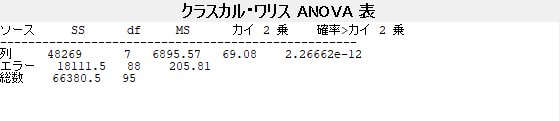

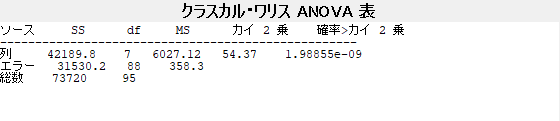

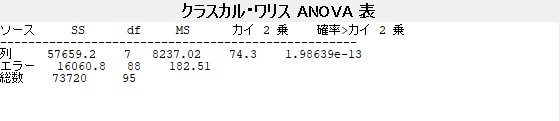

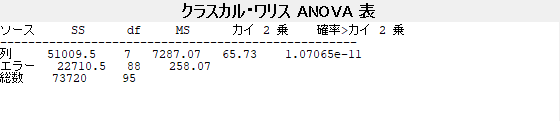

% 正規性の検定
% kstest h=1 => 正規分布であるという仮説はαで棄却
% kstest h=0 => 正規分布であるという仮説は棄却できない。
for i=1:4
    data = resCell{1,i};
    for k = 1:size(resCell{1,i},2)
        h = kstest(data(:,k));
        [resCell{4,i}(1,k), resCell{4,i}(2,k)] = kstest(data(:,k));
    end
    % 群間に違いがあるかの検定
    % ノンパラメトリック kruskalwallis（正規性でないのを確認）
    resCell{5,i} = kruskalwallis(data);
    
    % 多重比較検定

    
end

## 視線全体の mean std

% 
% for cond = 1:8
%     resGaze{cond,3} = reshape(mean(cell2mat(resGaze(cond,2))),[3,3]);
%     resGaze{cond,4} = reshape(std(cell2mat(resGaze(cond,2))),[3,3]);
%     figure('Position',[0 0 540 540])
% %     subplot(8,1,cond)
% %     h = heatmap(resGaze{cond,3});
% %     h.Title = {"Total mean" condName(cond,1)};
% %     set(gcf, 'visible', 'on')
% %     ax = gca; % current axes
% %     ax.FontSize = 12;
% %     ax.FontName = 'tahoma';
% %     saveas(gcf,strcat('heatmapMean_',condName(cond,1),'.png'));
% end

## 視線データ描画

% close all
% resGaze = cell(8,1);
% 
% % 各被験者フォルダにヒートマップ保存
% for subj = 1:12
%     folderNm = "sub" + num2str(subj);
%     cd(folderNm);
% 
%     figure('Position',[0 0 540 1920])
%     for cond = 1:8
% % %        個々人のヒートマップを描画
% %         figure('Position',[0 0 540 540])
% %         % h = heatmap(SubDatas{subj,4}{cond,1},"Title",condName(condNum,1))
% %         h = heatmap(SubDatas{subj,4}{cond,1})
% %         h.Title = {folderNm, condName(cond,1)};
% %         set(gcf, 'visible', 'on')
% %         ax = gca; % current axes
% %         ax.FontSize = 12;
% %         ax.FontName = 'tahoma';
% %         saveas(gcf,strcat('heatmap_',folderNm,'_',condName(cond,1),'.png'));
% %         close all
% 
%         subplot(8,1,cond)
%         h = heatmap(SubDatas{subj,4}{cond,1})
%         h.Title = {folderNm, condName(cond,1)};
%         ax = gca; % current axes
%         ax.FontSize = 12;
%         ax.FontName = 'tahoma';
%         % 全員分の平均とstdを集計
%         % Left=>Center=>Right
%         resGaze{cond,1} = condName(cond,1);
%         resGaze{cond,2}(subj,:) = reshape(SubDatas{subj,4}{cond,1},[1,9]);
%     end
% 
%     set(gcf, 'visible', 'on')
%     saveas(gcf,strcat('heatmap_all_',folderNm,'.png'));
%     cd ..
% end
% 
% close all

## 視線データ処理（ヒートマップ、アーカイブ）

% % SubDatas{subj,3} 1列目＝領域割合、2,3列目＝重心
% % load matlab.mat
% 
% % cell2mat(SubDatas{1,2}{[1,3,5],2})
% % SS = SubDatas{1,2}
% % SS{:,1}=[]
% 
% 
% subj = 1; cond = 1;
% 
% 
% for subj = 1:12
%     for cond = 1:8
%         % 初期設定
%         idxCell = cell(3,3);
% 
%         gazeHtMap = zeros(3,3); % 視線、9つの領域の出現率。SyubDatas 3 に追加
% 
%         % キャリブレーションの結果から補正
%         % x, y 共にそれぞれ横、縦の3点の平均を取って、オフセットする。  
%         calibArr = cell2mat(SubDatas{subj,2}(1:5,2:4));
%         xOffset = mean(calibArr([1,3,5],1));
%         yOffset = mean(calibArr([1,2,4],1));
% 
%         for k = 1:2 % 1 = 全て、2 = ターゲットが見えていないとき
%             if k==1
%                gaze = SubDatas{subj,1}{cond,1}(:,9:10);
%             else
%                invisTar = SubDatas{subj,1}{cond,1}(:,8) == 0;
%                gaze = SubDatas{subj,1}{cond,1}(invisTar,9:10);
%             end
%             gaze(:,1) = gaze(:,1) + xOffset;
%             gaze(:,2) = gaze(:,2) + yOffset;
%             gzX = gaze(:,1);
%             gzY = gaze(:,2);
% 
%             % ヒートマップ作成    
% %             % 9つの領域の出現率を計算、代入
% %             bdx = 1/6; % 領域の境界線
% %             idxCell{1,1} = gzX < -bd & gzY > bd;
% %             idxCell{1,2} = gzX >= -bd & gzX <= bd & gzY > bd;
% %             idxCell{1,3} = gzX > bd & gzY > bd;
% %             idxCell{2,1} = gzX < -bd & gzY >= -bd & gzY <= bd;
% %             idxCell{2,2} = gzX >= -bd & gzX <= bd & gzY >= -bd & gzY <= bd;
% %             idxCell{2,3} = gzX > bd & gzY >= -bd & gzY <= bd;
% %             idxCell{3,1} = gzX < -bd & gzY < -bd;
% %             idxCell{3,2} = gzX >= -bd & gzX <= bd & gzY < -bd;
% %             idxCell{3,3} = gzX > bd & gzY < -bd;
% 
% %             図示用 
% %             for col = 1:3
% %                 for row = 1:3
% %                     gazeHtMap(row, col) = size(gaze(idxCell{row,col},:),1) / size(gaze,1) * 100;
% %                 end
% %             end
% %             
% %             % 重心散布図
% %             Xg = mean(gaze(:,1)) + xOffset; % xの重心
% %             Yg = mean(gaze(:,2)) + yOffset; % yの重心
% %             
% %             % データまとめ
% %             SubDatas{subj,2+k}{cond,1} = gazeHtMap;
% %             SubDatas{subj,2+k}{cond,2} = Xg;
% %             SubDatas{subj,2+k}{cond,3} = Yg;    
% %             SubDatas{subj,2+k}{cond,4} = condName(cond,1);    
% 
%                 
%            
%         end
%     end
% end
% 
% save;